## 程序说明

% 本程序用于受力分析，主要是绘图
% 以斯格明子场中的粒子为分析对象
% 用到的数据集来自脚本"caculate_optical_force"
% 2023/09/04 20:53


## 初始化参数

% load('optiForce_workspace_020.mat') % 从工作区载入数据
stepsize = linspace(-1e-6,1e-6,sampling_point); % 轴坐标范围设置
center_sweep_line = (1+sampling_point)/2;

% 扫描数据载入,水平中心行
scan_Fx=Fx(center_sweep_line,:); % 总力

scan_F_gradx = F_gradx(center_sweep_line,:); % 八项
scan_F_radx = F_radx(center_sweep_line,:);
scan_F_vorx = F_vorx(center_sweep_line,:);
scan_F_curlex = F_curlex(center_sweep_line,:);
scan_F_curlhx = F_curlhx(center_sweep_line,:);
scan_F_spinex = F_spinex(center_sweep_line,:);
scan_F_spinmx = F_spinmx(center_sweep_line,:);
scan_F_flowx = F_flowx(center_sweep_line,:);

scan_F_curlx = F_curlx(center_sweep_line,:); % 并项
scan_F_spinx = F_spinx(center_sweep_line,:);


scan_Fy=Fy(center_sweep_line,:); % 总力

scan_F_grady = F_grady(center_sweep_line,:); % 八项
scan_F_rady = F_rady(center_sweep_line,:);
scan_F_vory = F_vory(center_sweep_line,:);
scan_F_curley = F_curley(center_sweep_line,:);
scan_F_curlhy = F_curlhy(center_sweep_line,:);
scan_F_spiney = F_spiney(center_sweep_line,:);
scan_F_spinmy = F_spinmy(center_sweep_line,:);
scan_F_flowy = F_flowy(center_sweep_line,:);

scan_F_curly = F_curly(center_sweep_line,:); % 并项
scan_F_spiny = F_spiny(center_sweep_line,:);

## 手性粒子 x 方向的受力分析

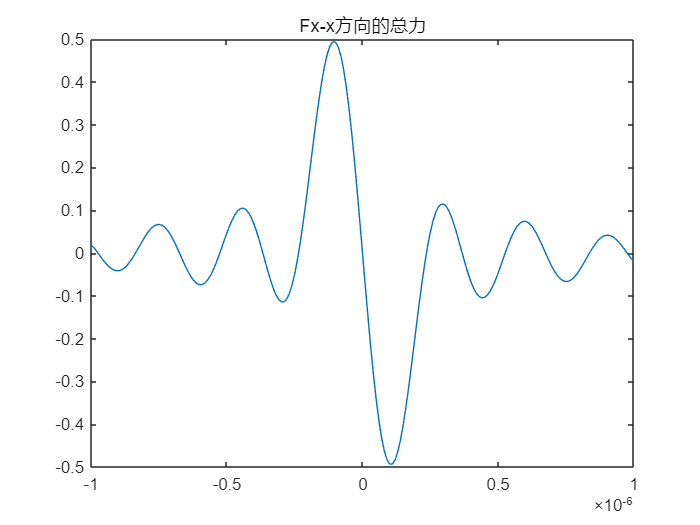

% 绘制总力
figure;plot(stepsize,scan_Fx);title('Fx-x方向的总力')

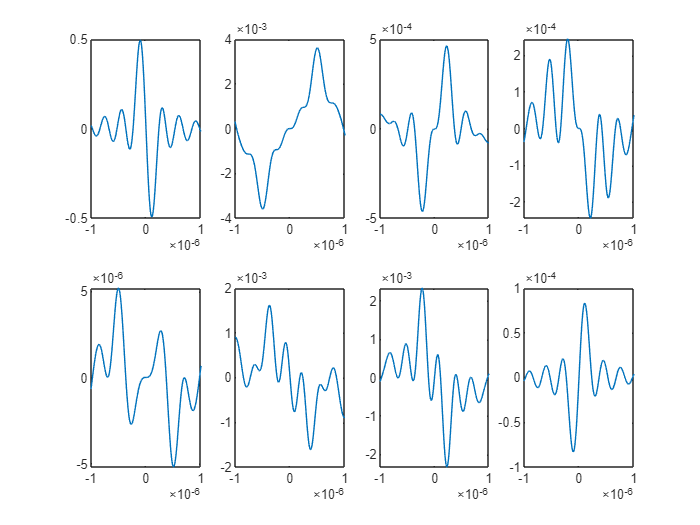


% 绘制分力
figure;title('x方向的8项分力');hold on
subplot(2,4,1);plot(stepsize,scan_F_gradx);
subplot(2,4,2);plot(stepsize,scan_F_radx);
subplot(2,4,3);plot(stepsize,scan_F_vorx);
subplot(2,4,4);plot(stepsize,scan_F_curlex);
subplot(2,4,5);plot(stepsize,scan_F_curlhx);
subplot(2,4,6);plot(stepsize,scan_F_spinex);
subplot(2,4,7);plot(stepsize,scan_F_spinmx);
subplot(2,4,8);plot(stepsize,scan_F_flowx);

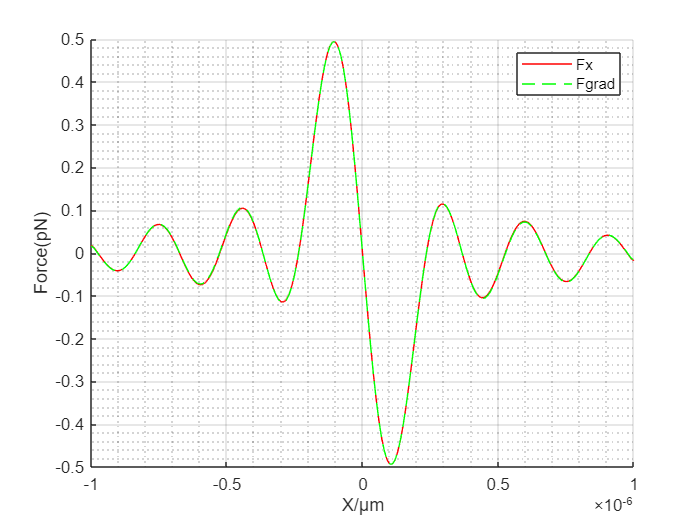


% 总力与梯度力的关系
figure;hold on
plot(stepsize,scan_Fx,Color='red'); % x 方向的总力
plot(stepsize,scan_F_gradx,'--',Color='green'); % 梯度力
legend('Fx','Fgrad');grid on; grid minor;
xlabel('X/{\mu}m');ylabel('Force(pN)');

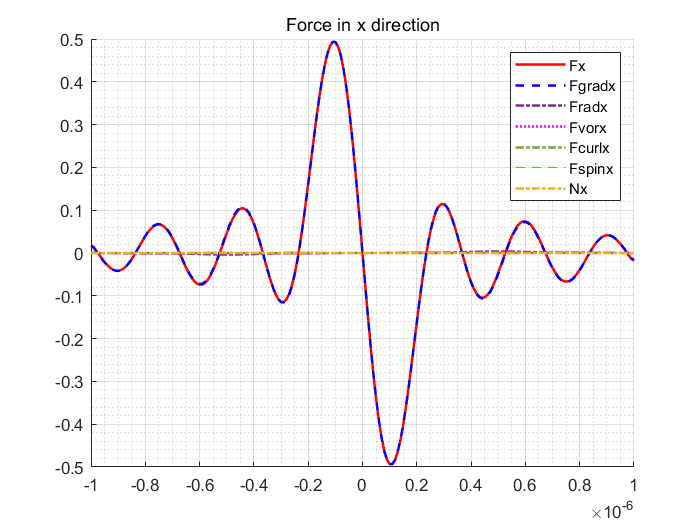

% 分析 x 方向所有的力的关系
figure;title('Force in x direction');hold on
plot(stepsize,scan_Fx,Color='red',LineWidth=1.5);
plot(stepsize,scan_F_gradx,'--',Color='blue',LineWidth=1.5);
plot(stepsize,scan_F_radx,'-.',Color=[0.4940 0.1840 0.5560],LineWidth=1.5);
plot(stepsize,scan_F_vorx,':',Color='magenta',LineWidth=1.5);
plot(stepsize,scan_F_curlx,'-.',Color=[0.4660 0.6740 0.1880],LineWidth=1.5);
plot(stepsize,scan_F_spinx,'--',Color='green'),LineWidth=1.5;
plot(stepsize,scan_F_flowx,'-.',Color=[0.9290 0.6940 0.1250],LineWidth=1.5);
legend('Fx','Fgradx','Fradx','Fvorx','Fcurlx','Fspinx','Nx');grid on;grid minor;

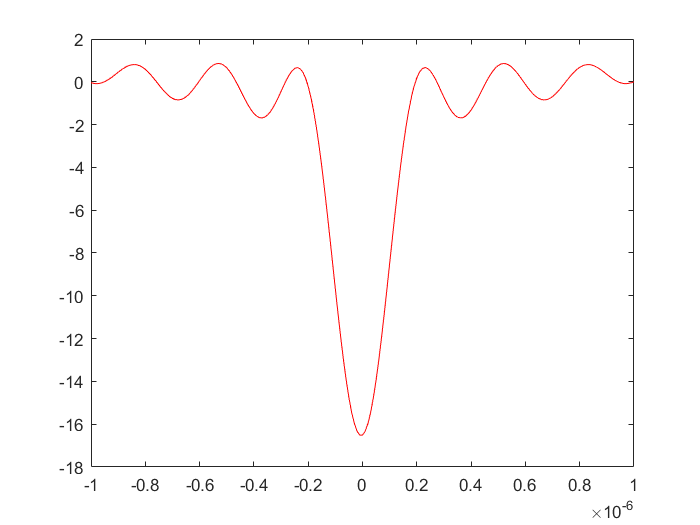


% plasmonic trapping potential energy 势阱
scan_Fx_potential = scan_Fx*1e-12;
[h,w]=size(scan_Fx_potential);
Tx=zeros(h,w);
for i=2:w
    Tx(1)=scan_Fx_potential(1).*(scale);
    Tx(1,i)=Tx(1,i-1)+scan_Fx_potential(1,i).*(scale);
end
KbT=4.14*10^-21;
Tx=-(Tx/KbT);
figure;plot(stepsize,Tx,'r-');

## 手性粒子 y 方向的受力分析

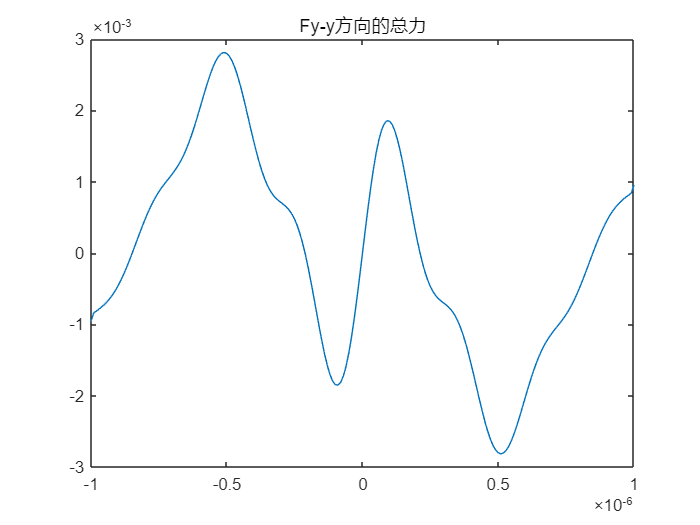

% 绘制总力
figure;plot(stepsize,scan_Fy);title('Fy-y方向的总力')

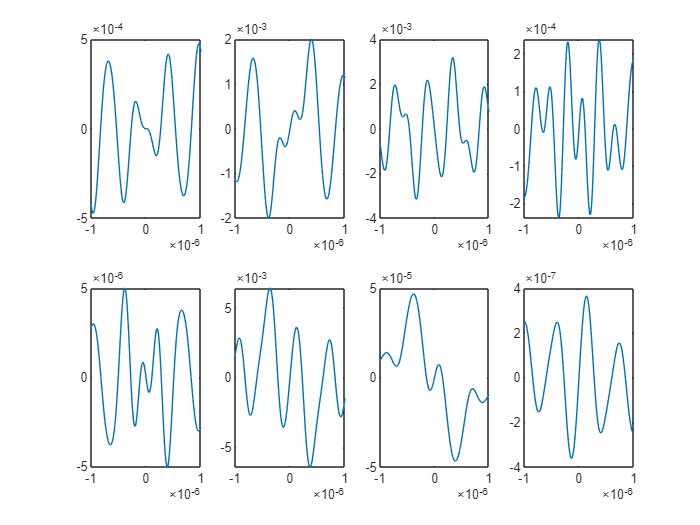


% 绘制分力
figure;title('y方向的8项分力');hold on
subplot(2,4,1);plot(stepsize,scan_F_grady);
subplot(2,4,2);plot(stepsize,scan_F_rady);
subplot(2,4,3);plot(stepsize,scan_F_vory);
subplot(2,4,4);plot(stepsize,scan_F_curley);
subplot(2,4,5);plot(stepsize,scan_F_curlhy);
subplot(2,4,6);plot(stepsize,scan_F_spiney);
subplot(2,4,7);plot(stepsize,scan_F_spinmy);
subplot(2,4,8);plot(stepsize,scan_F_flowy);

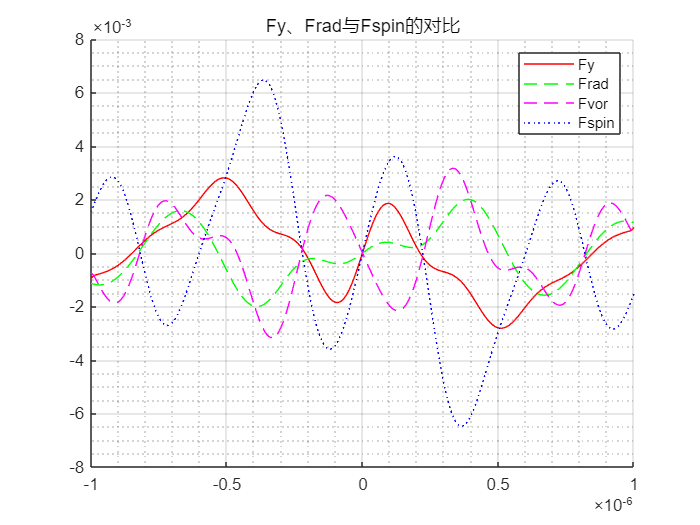


% % 计算并绘制散射力 F_sca 与自旋力 F_spin
% figure;hold on 
% subplot(1,2,1);plot(stepsize,scan_F_sca);title('F_{sca}')
% subplot(1,2,2);plot(stepsize,scan_F_spiny);title('F_{spin}')

% 分析Fy、Frad与Fspin的关系
figure;title('Fy、Frad与Fspin的对比');hold on
plot(stepsize,scan_Fy,Color='red');
plot(stepsize,scan_F_rady,'--',Color='green');
plot(stepsize,scan_F_vory,'--',Color='magenta');
plot(stepsize,scan_F_spiny,':',Color='blue');
legend('Fy','Frad','Fvor','Fspin');grid on;grid minor;

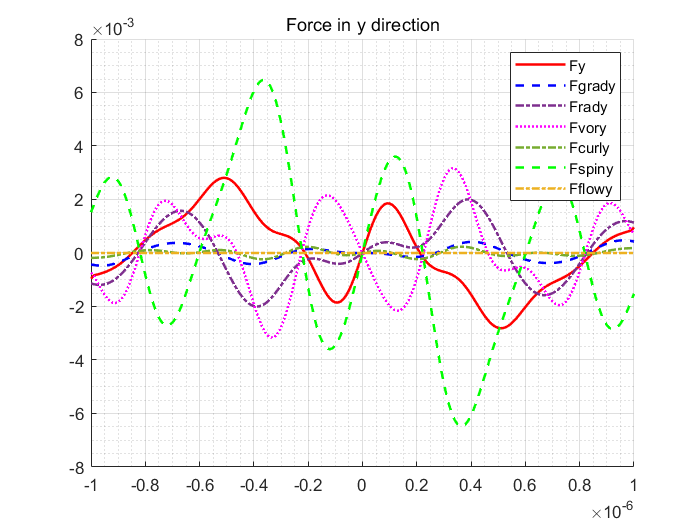


% 分析 y 方向所有的力的关系
figure;title('Force in y direction');hold on
plot(stepsize,scan_Fy,Color='red',LineWidth=1.5);
plot(stepsize,scan_F_grady,'--',Color='blue',LineWidth=1.5);
plot(stepsize,scan_F_rady,'-.',Color=[0.4940 0.1840 0.5560],LineWidth=1.5);
plot(stepsize,scan_F_vory,':',Color='magenta',LineWidth=1.5);
plot(stepsize,scan_F_curly,'-.',Color=[0.4660 0.6740 0.1880],LineWidth=1.5);
plot(stepsize,scan_F_spiny,'--',Color='green',LineWidth=1.5);
plot(stepsize,scan_F_flowy,'-.',Color=[0.9290 0.6940 0.1250],LineWidth=1.5);
legend('Fy','Fgrady','Frady','Fvory','Fcurly','Fspiny','Fflowy');grid on;grid minor;